syms q1 q2 l1 l2

% Transformate
T0_1 = [cos(q1)  sin(q1)    0      0;   %rotatie axa Z
        -sin(q1) cos(q1)    0      0;    
          0         0       1      0;
          0         0       0      1];

T1_2 = [1       0         0         l1;     %rotatie 1 -> 2, axa X + translatie l1, axa Z
        0       1         0         0;    
        0       0         1         0;
        0       0         0        1];

T2_e = [1   0   0   q2;   %translatie 2 -> e, axa Z, l2
        0   1   0   0;
        0   0   1   0;
        0   0   0   1];


T0_2 = T0_1 * T1_2

$$T0\_2 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 & l_{1}\,\cos\left(q_{1}\right)\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & -l_{1}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T0_e = T0_2 * T2_e

$$T0\_e = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 & l_{1}\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & -l_{1}\,\sin\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


% Pozitii + rotatii cuple
P0_1 = T0_1((1:3), 4)

$$P0\_1 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

P0_2 = T0_2((1:3), 4)

$$P0\_2 = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\right)\\ -l_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

P0_e = T0_e((1:3), 4)

$$P0\_e = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ -l_{1}\,\sin\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$


R0_1 = T0_1((1:3), (1:3))

$$R0\_1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R0_2 = T0_2((1:3), (1:3))

$$R0\_2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R0_e = T0_e((1:3), (1:3))

$$R0\_e = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


R2_e = T2_e((1:3), (1:3))

$$R2\_e = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

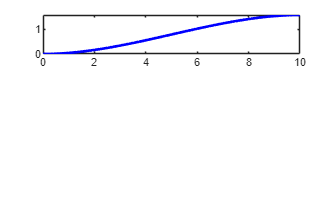

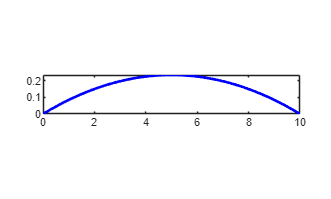

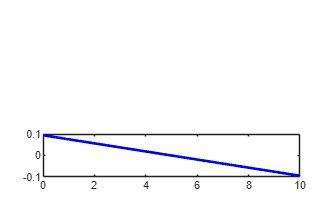

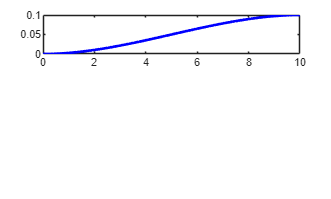

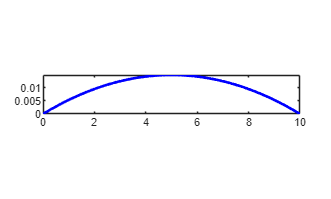

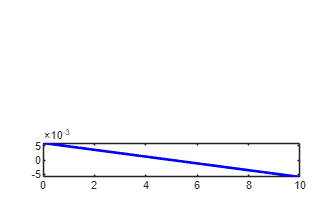

pvc =          0    0.0005    0.0019    0.0042    0.0075    0.0116    0.0166    0.0224    0.0291    0.0366    0.0448    0.0539    0.0636    0.0741    0.0854    0.0973    0.1098    0.1230    0.1369    0.1514    0.1664    0.1821    0.1982    0.2150    0.2322    0.2499    0.2681    0.2868    0.3059    0.3254    0.3453    0.3656    0.3863    0.4072    0.4286    0.4502    0.4721    0.4942    0.5166    0.5392    0.5621    0.5851    0.6083    0.6316    0.6550    0.6786    0.7022    0.7259    0.7497    0.7735
         0    0.0000    0.0001    0.0003    0.0005    0.0007    0.0011    0.0014    0.0019    0.0023    0.0029    0.0034    0.0041    0.0047    0.0054    0.0062    0.0070    0.0078    0.0087    0.0096    0.0106    0.0116    0.0126    0.0137    0.0148    0.0159    0.0171    0.0183    0.0195    0.0207    0.0220    0.0233    0.0246    0.0259    0.0273    0.0287    0.0301    0.0315    0.0329    0.0343    0.0358    0.0372    0.0387    0.0402    0.0417    0.0432    0.0447    0.0462    0.0477   

Qdorit1 =          0         0
    0.1010    0.0005
    0.2020    0.0019
    0.3030    0.0042
    0.4040    0.0075
    0.5051    0.0116
    0.6061    0.0166
    0.7071    0.0224
    0.8081    0.0291
    0.9091    0.0366
    1.0101    0.0448
    1.1111    0.0539
    1.2121    0.0636
    1.3131    0.0741
    1.4141    0.0854


dQdorit1 =          0         0
    0.1010    0.0094
    0.2020    0.0187
    0.3030    0.0277
    0.4040    0.0365
    0.5051    0.0452
    0.6061    0.0537
    0.7071    0.0619
    0.8081    0.0700
    0.9091    0.0779
    1.0101    0.0856
    1.1111    0.0931
    1.2121    0.1004
    1.3131    0.1075
    1.4141    0.1144


ddQdorit1 =          0    0.0942
    0.1010    0.0923
    0.2020    0.0904
    0.3030    0.0885
    0.4040    0.0866
    0.5051    0.0847
    0.6061    0.0828
    0.7071    0.0809
    0.8081    0.0790
    0.9091    0.0771
    1.0101    0.0752
    1.1111    0.0733
    1.2121    0.0714
    1.3131    0.0695
    1.4141    0.0676


Qdorit2 =          0         0
    0.1010    0.0000
    0.2020    0.0001
    0.3030    0.0003
    0.4040    0.0005
    0.5051    0.0007
    0.6061    0.0011
    0.7071    0.0014
    0.8081    0.0019
    0.9091    0.0023
    1.0101    0.0029
    1.1111    0.0034
    1.2121    0.0041
    1.3131    0.0047
    1.4141    0.0054


dQdorit2 =          0         0
    0.1010    0.0006
    0.2020    0.0012
    0.3030    0.0018
    0.4040    0.0023
    0.5051    0.0029
    0.6061    0.0034
    0.7071    0.0039
    0.8081    0.0045
    0.9091    0.0050
    1.0101    0.0054
    1.1111    0.0059
    1.2121    0.0064
    1.3131    0.0068
    1.4141    0.0073


ddQdorit2 =          0    0.0060
    0.1010    0.0059
    0.2020    0.0058
    0.3030    0.0056
    0.4040    0.0055
    0.5051    0.0054
    0.6061    0.0053
    0.7071    0.0052
    0.8081    0.0050
    0.9091    0.0049
    1.0101    0.0048
    1.1111    0.0047
    1.2121    0.0045
    1.3131    0.0044
    1.4141    0.0043


qr=[0,pi/2;...
   0,0.1];

T=10; 
n=100;

pvc=traiectSCR(qr,T,n,1);

syms lc1 lc2
%centru de greutate
pc1 = subs(P0_2, l1, lc1)

$$pc1 = \left(\begin{array}{c} {\mathrm{lc}}_{1}\,\cos\left(q_{1}\right)\\ -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

pc2 = subs(P0_e, l2, lc2)

$$pc2 = \left(\begin{array}{c} l_{1}\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\\ -l_{1}\,\sin\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

rc1 = R0_1

$$rc1 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

rc2 = R0_2

$$rc2 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0\\ -\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

[J1, J2, J3, J4] = jacobianMatrixSCARA(pc1, pc2, q1, q2, rc1, rc2, T1_2)

$$Jv1 = \left(\begin{array}{cc} -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\right) & 0\\ -{\mathrm{lc}}_{1}\,\cos\left(q_{1}\right) & 0\\ 0 & 0 \end{array}\right)$$

$$Jv2 = \left(\begin{array}{cc} -l_{1}\,\sin\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ -l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

delta1 =      0
     0
     1


delta2 =      0
     0
     0


$$r11 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

$$r21 = \left(\begin{array}{c} 0\\ 0\\ 1 \end{array}\right)$$

r12 =      0
     0
     0


$$r22 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

$$Jomega1 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

$$Jomega2 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

$$J1 = \left(\begin{array}{cc} -{\mathrm{lc}}_{1}\,\sin\left(q_{1}\right) & 0\\ -{\mathrm{lc}}_{1}\,\cos\left(q_{1}\right) & 0\\ 0 & 0 \end{array}\right)$$

$$J2 = \left(\begin{array}{cc} -l_{1}\,\sin\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ -l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right)\\ 0 & 0 \end{array}\right)$$

$$J3 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

$$J4 = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 1 & 0 \end{array}\right)$$

Mq = inertiaMatrix(J1, J2, J3, J4)

$$Ic1 = \left(\begin{array}{ccc} {\mathrm{Ixx}}_{1} & 0 & 0\\ 0 & {\mathrm{Iyy}}_{1} & 0\\ 0 & 0 & {\mathrm{Izz}}_{1} \end{array}\right)$$

$$Ic2 = \left(\begin{array}{ccc} {\mathrm{Ixx}}_{2} & 0 & 0\\ 0 & {\mathrm{Iyy}}_{2} & 0\\ 0 & 0 & {\mathrm{Izz}}_{2} \end{array}\right)$$

$$Mv = \left(\begin{array}{cc} {\mathrm{mc}}_{2}\,{l_{1}}^{2}+2\,{\mathrm{mc}}_{2}\,l_{1}\,q_{2}+{\mathrm{mc}}_{1}\,{{\mathrm{lc}}_{1}}^{2}+{\mathrm{mc}}_{2}\,{q_{2}}^{2} & 0\\ 0 & {\mathrm{mc}}_{2} \end{array}\right)$$

$$Momega = \left(\begin{array}{cc} {\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2} & 0\\ 0 & 0 \end{array}\right)$$

$$M = \left(\begin{array}{cc} {\mathrm{mc}}_{2}\,{l_{1}}^{2}+2\,{\mathrm{mc}}_{2}\,l_{1}\,q_{2}+{\mathrm{mc}}_{1}\,{{\mathrm{lc}}_{1}}^{2}+{\mathrm{mc}}_{2}\,{q_{2}}^{2}+{\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2} & 0\\ 0 & {\mathrm{mc}}_{2} \end{array}\right)$$

$$Mq = \left(\begin{array}{cc} {\mathrm{mc}}_{2}\,{l_{1}}^{2}+2\,{\mathrm{mc}}_{2}\,l_{1}\,q_{2}+{\mathrm{mc}}_{1}\,{{\mathrm{lc}}_{1}}^{2}+{\mathrm{mc}}_{2}\,{q_{2}}^{2}+{\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2} & 0\\ 0 & {\mathrm{mc}}_{2} \end{array}\right)$$

Cn = centrifugalMatrix(Mq)

$$Cn = \left(\begin{array}{cc} 0 & 0\\ -{\mathrm{mc}}_{2}\,\left(l_{1}+q_{2}\right) & 0 \end{array}\right)$$

B = coriolisMatrix(Mq)

$$B = \left(\begin{array}{c} 2\,{\mathrm{mc}}_{2}\,\left(l_{1}+q_{2}\right)\\ 0 \end{array}\right)$$

G = gravityMatrix(J1, J2)

$$G = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

syms ddq1 ddq2 dq1 dq2
Tau = Mq * [ddq1; ddq2] + B * [dq1*dq2] + Cn * [dq1^2; dq2^2] + G

$$Tau = \left(\begin{array}{c} {\mathrm{ddq}}_{1}\,\left({\mathrm{mc}}_{2}\,{l_{1}}^{2}+2\,{\mathrm{mc}}_{2}\,l_{1}\,q_{2}+{\mathrm{mc}}_{1}\,{{\mathrm{lc}}_{1}}^{2}+{\mathrm{mc}}_{2}\,{q_{2}}^{2}+{\mathrm{Izz}}_{1}+{\mathrm{Izz}}_{2}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,{\mathrm{mc}}_{2}\,\left(l_{1}+q_{2}\right)\\ {\mathrm{ddq}}_{2}\,{\mathrm{mc}}_{2}-{{\mathrm{dq}}_{1}}^{2}\,{\mathrm{mc}}_{2}\,\left(l_{1}+q_{2}\right) \end{array}\right)$$

d1 = diff(P0_e, q1)

$$d1 = \left(\begin{array}{c} -l_{1}\,\sin\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right)\\ -l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\cos\left(q_{1}\right)\\ 0 \end{array}\right)$$

d2 = diff(P0_e, q2)

$$d2 = \left(\begin{array}{c} \cos\left(q_{1}\right)\\ -\sin\left(q_{1}\right)\\ 0 \end{array}\right)$$

jve=[d1(1), d2(1); d1(2) , d2(2)]

$$jve = \left(\begin{array}{cc} -l_{1}\,\sin\left(q_{1}\right)-q_{2}\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\\ -l_{1}\,\cos\left(q_{1}\right)-q_{2}\,\cos\left(q_{1}\right) & -\sin\left(q_{1}\right) \end{array}\right)$$

jve_d = diff(jve, q1) * dq1 + diff(jve, q2) * dq2

$$jve\_d = \left(\begin{array}{cc} -{\mathrm{dq}}_{1}\,\left(l_{1}\,\cos\left(q_{1}\right)+q_{2}\,\cos\left(q_{1}\right)\right)-{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right) & -{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right)\\ {\mathrm{dq}}_{1}\,\left(l_{1}\,\sin\left(q_{1}\right)+q_{2}\,\sin\left(q_{1}\right)\right)-{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right) & -{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right) \end{array}\right)$$

save trajectories.mat

clear
load("Qdorit1.mat");
load("Qdorit2.mat");
addpath(fullfile(pwd, 'FUNCTIILE_MELE'))

load("trajectories.mat");

modelName = 'control_clasic';

load_system(modelName);
out = sim(modelName);

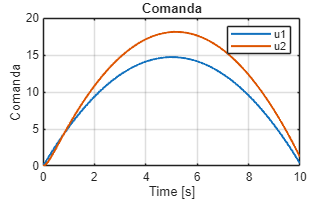

comanda  = out.comanda_u1_u2;
erori_Q  = out.erori_pozitie_Q;
torque   = out.torque;

comanda_data = squeeze(comanda.Data);
erori_Q_data = squeeze(erori_Q.Data);
torque_data  = squeeze(torque.Data);

figure
plot(comanda.Time, comanda_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Comanda')
title('Comanda')
legend('u1', 'u2')

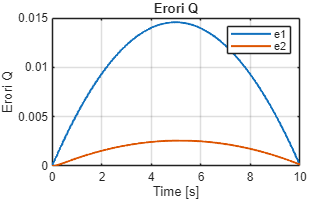


figure
plot(erori_Q.Time, erori_Q_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Erori Q')
title('Erori Q')
legend('e1', 'e2')

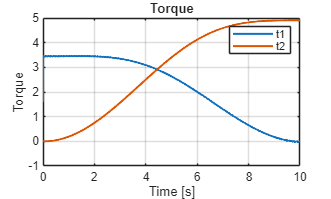


figure
plot(torque.Time, torque_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Torque')
title('Torque')
legend('t1', 't2')

modelName = 'control_invers';

load("dQdorit1.mat");
load("dQdorit2.mat");
load("ddQdorit1.mat");
load("ddQdorit2.mat");
load_system(modelName);
out = sim(modelName);

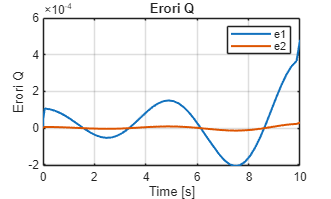

erori_Q  = out.erori_Q;
erori_dQ  = out.erori_dQ;
torque   = out.torque;

erori_Q_data = squeeze(erori_Q.Data);
erori_dQ_data = squeeze(erori_dQ.Data);
torque_data  = squeeze(torque.Data);

figure
plot(erori_Q.Time, erori_Q_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Erori Q')
title('Erori Q')
legend('e1', 'e2')

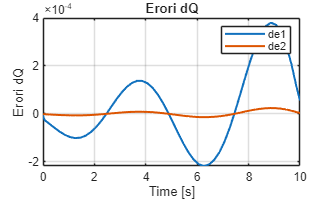


figure
plot(erori_dQ.Time, erori_dQ_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Erori dQ')
title('Erori dQ')
legend('de1', 'de2')

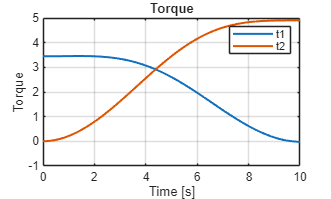


figure
plot(torque.Time, torque_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Torque')
title('Torque')
legend('t1', 't2')

modelName = 'control_holist';

load_system(modelName);
out = sim(modelName);

Invalid setting in 'control_holist/Traiectorie/From Workspace' for parameter 'VariableName'.

Caused by:
    Error using mainSCARA (line 144)
    Error evaluating parameter 'VariableName' in 'control_holist/Traiectorie/From Workspace'
        Error using 

erori_Q  = out.erori_Q;
erori_dQ  = out.erori_dQ;
comanda   = out.comanda;

Unrecognized field name "comanda".


erori_Q_data = squeeze(erori_Q.Data);
erori_dQ_data = squeeze(erori_dQ.Data);
comanda_data  = squeeze(comanda.Data);

figure
plot(erori_Q.Time, erori_Q_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Erori Q')
title('Erori Q')
legend('e1', 'e2')

figure
plot(erori_dQ.Time, erori_dQ_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Erori dQ')
title('Erori dQ')
legend('de1', 'de2')

figure
plot(comanda.Time, comanda_data, 'LineWidth', 1.5)
grid on
xlabel('Time [s]')
ylabel('Voltaj')
title('Comanda')
legend('t1', 't2')


